## **K-Means using Euclidean distance**

### **On Salinas Data**

%Loading image
addpath('data')
image = load("Salinas_corrected.mat");
Salinas_Image = image.salinas_corrected;
[p1,n1,l]=size(Salinas_Image);
X=reshape(Salinas_Image,p1*n1,l);
X=X';
%Loading ground truth image
gt = load("Salinas_gt.mat");
Salinas_Labels = gt.salinas_gt;
[p2,n2]=size(Salinas_Labels);
y=reshape(Salinas_Labels,p2*n2,1);
y=y';%Remove zero class labels
zero_idx=find(~y);
nonzero_idx=find(y);
X(:,zero_idx)=[];
y(:,zero_idx)=[];
[l,N]=size(X);

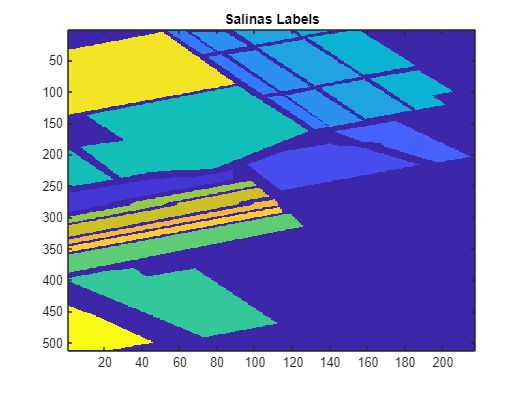

%% Visualizations %%
im=Salinas_Labels;
figure(1), imagesc(im);
title('Salinas Labels');
hold off

prompt = "What is the number of components? ";
n = input(prompt)

n = 16

prompt = "What is the lower k value? ";
k1 = input(prompt)

k1 = 7

prompt = "What is the higher k value? ";
k2 = input(prompt)

k2 = 19

%% Filtering and Normalization %%

%X=imgaussfilt(X,3.5,'FilterSize',9);
%X=normalize(X);

%% Dimensionality Reduction with PCA %%

[eigenval,eigenvec,explain,Y,mean_vec]=pca_fun(X,n);
X=Y;
[l,N]=size(X);

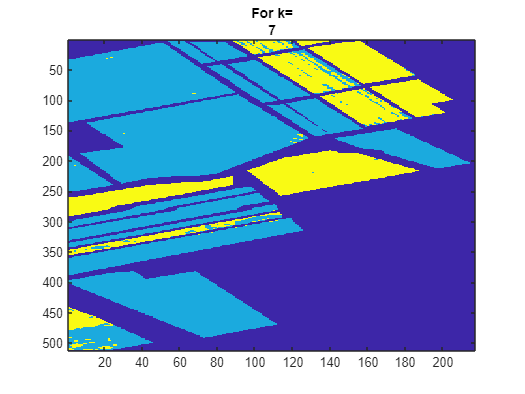

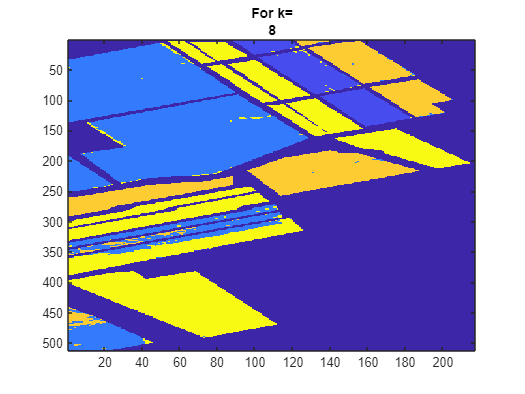

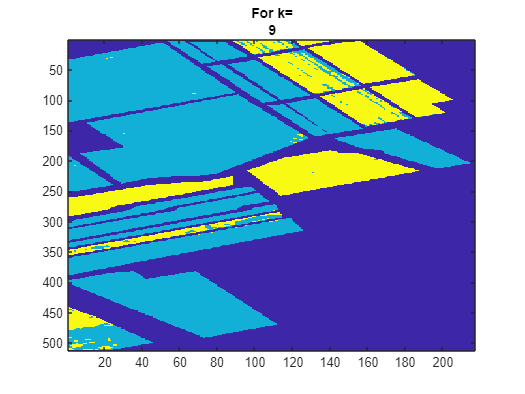

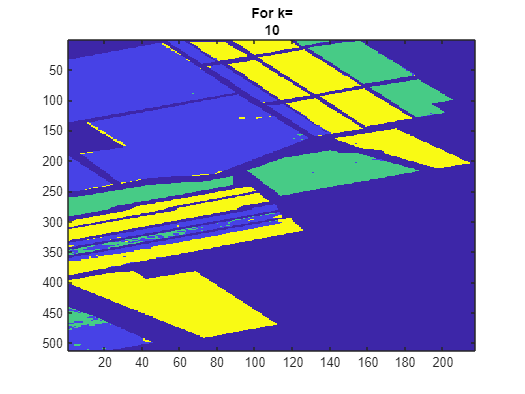

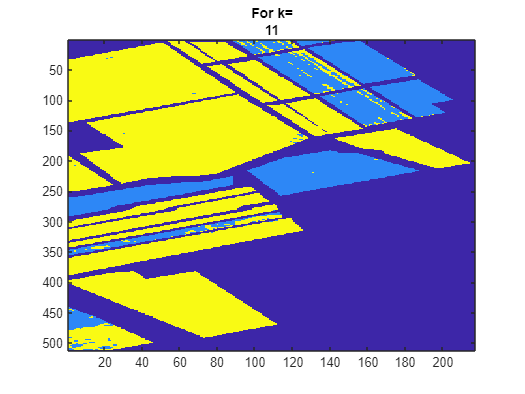

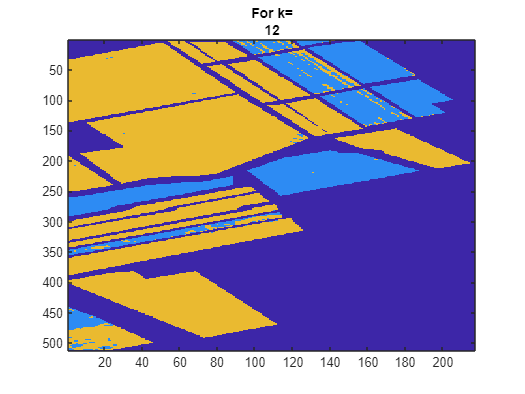

for m=k1:k2
    
    costs=[];
    bels=[];

    for i=1:15
        theta_init=rand(l,m);
        [theta,bel,J]=k_means(X,theta_init);
        bels=[bels;bel];
        costs=[costs;J];
    end

    %figure(3),plot(costs)
    %[cost_m,bel_index]=min(costs);
    %bel=bels(bel_index,:);

    cl_label=bel';
    cl_label_tot=zeros(p1*n1,1);
    cl_label_tot(nonzero_idx)=cl_label;
    im_cl_label=reshape(cl_label_tot,p1,n1);
    figure(m), imagesc(im_cl_label);
    title(['For k=' {m}])

end

### **On Indian Pines data**

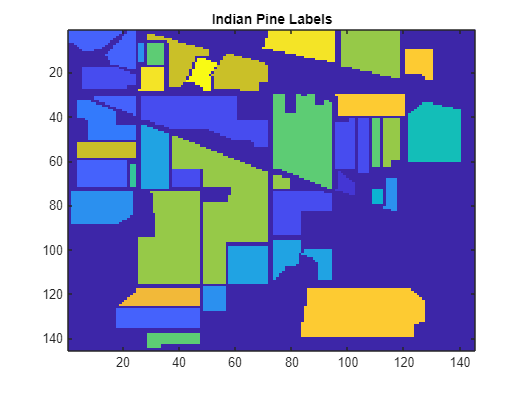

image = load("Indian_pines_corrected.mat");
Indian_pine_Image = image.indian_pines_corrected;
[p1,n1,l]=size(Indian_pine_Image);
X=reshape(Indian_pine_Image,p1*n1,l);
X=X';
gt = load("Indian_pines_gt.mat");
indian_Labels = gt.indian_pines_gt;
[p2,n2]=size(indian_Labels);
y=reshape(indian_Labels,p2*n2,1);
y=y';
zero_idx=find(~y);
nonzero_idx=find(y);
X(:,zero_idx)=[];
y(:,zero_idx)=[];
[l,N]=size(X);
%% Visualizations %%

im=indian_Labels;
figure(1), imagesc(im);
title('Indian Pine Labels');
hold off

prompt = "What is the number of components? ";
n = input(prompt)

n = 16

prompt = "What is the lower k value? ";
k1 = input(prompt)

k1 = 5

prompt = "What is the higher k value? ";
k2 = input(prompt)

k2 = 15

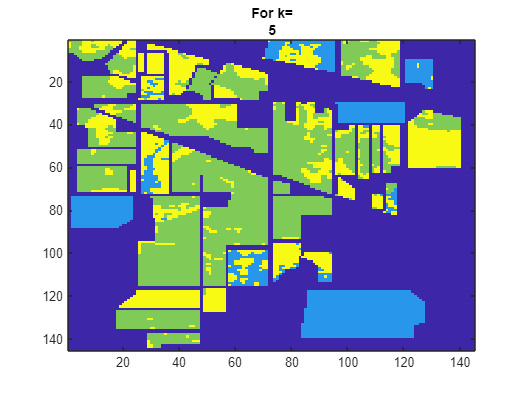

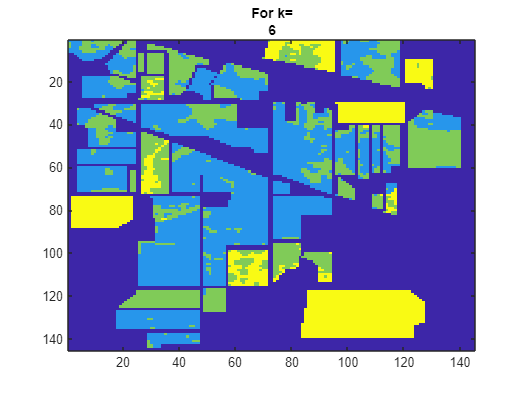

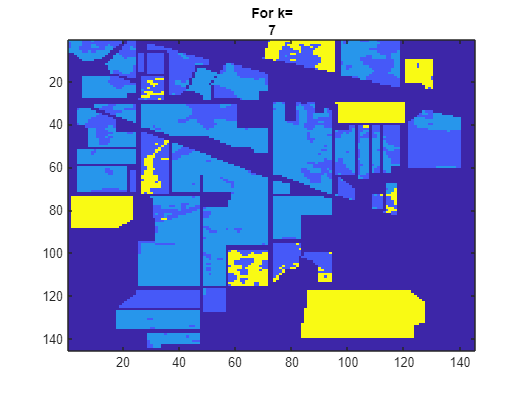

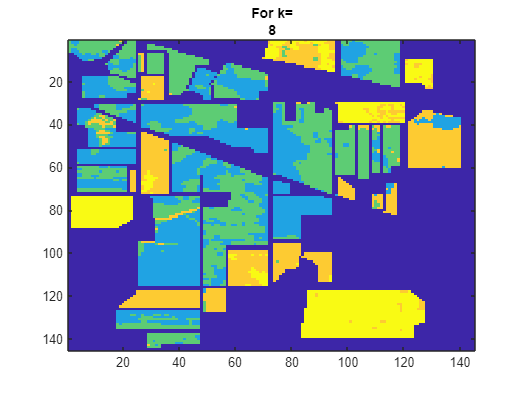

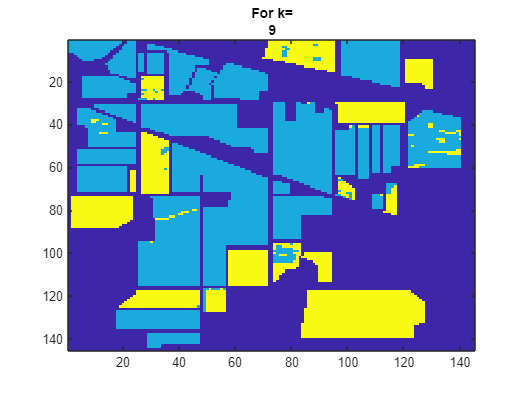

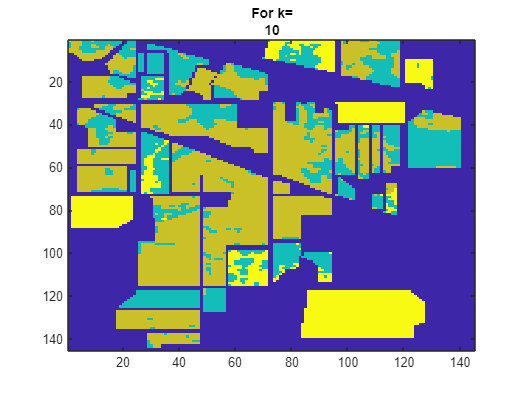

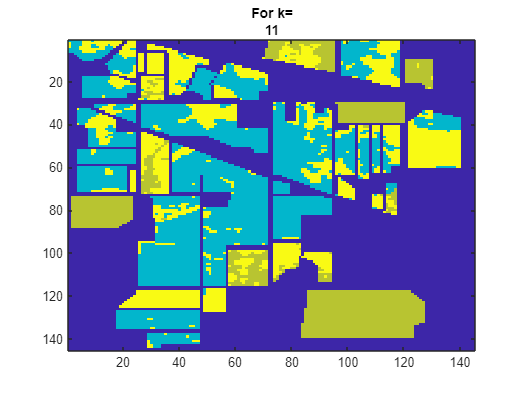

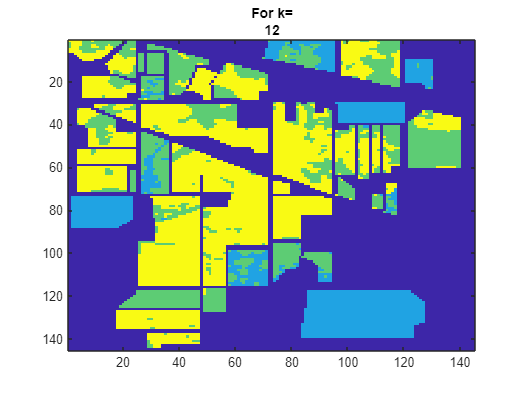


%% Filtering and Normalization %%

%X=imgaussfilt(X,3.5,'FilterSize',9);
%X=normalize(X);

%% Dimensionality Reduction with PCA %%

[eigenval,eigenvec,explain,Y,mean_vec]=pca_fun(X,n);
X=Y;
[l,N]=size(X);

rand_k_means_all=[];
jaccard_k_means_all=[];

for m=k1:k2
    
    costs=[];
    bels=[];

    for i=1:15
        theta_init=rand(l,m);
        [theta,bel,J]=k_means(X,theta_init);
        bels=[bels;bel];
        costs=[costs;J];
    end

    %figure(3),plot(costs)
    [cost_m,bel_index]=min(costs);
    bel=bels(bel_index,:);

    cl_label=bel';
    cl_label_tot=zeros(p1*n1,1);
    cl_label_tot(nonzero_idx)=cl_label;
    im_cl_label=reshape(cl_label_tot,p1,n1);
    figure(m), imagesc(im_cl_label); 
    title(['For k=' {m}])

end

### **On Salinas-A Data**

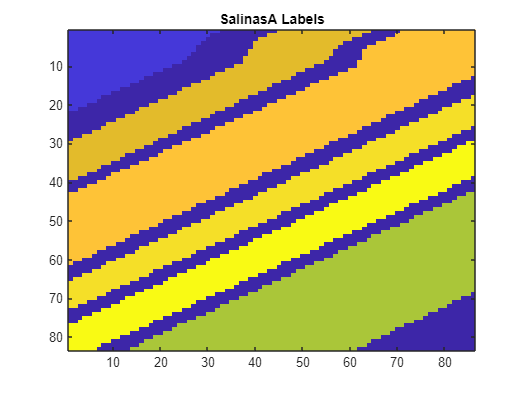

image = load("SalinasA_corrected.mat");
Image = image.salinasA_corrected;
[p1,n1,l]=size(Image);
X=reshape(Image,p1*n1,l);
X=X';
gt = load("SalinasA_gt.mat");
Labels = gt.salinasA_gt;
[p2,n2]=size(Labels);
y=reshape(Labels,p2*n2,1);
y=y';
zero_idx=find(~y);
nonzero_idx=find(y);
X(:,zero_idx)=[];
y(:,zero_idx)=[];
[l,N]=size(X);
%% Visualizations %%

im=Labels;
figure(1), imagesc(im);
title('SalinasA Labels');
hold off

prompt = "What is the number of components? ";
n = input(prompt)

n = 6

prompt = "What is the lower k value? ";
k1 = input(prompt)

k1 = 3

prompt = "What is the higher k value? ";
k2 = input(prompt)

k2 = 14

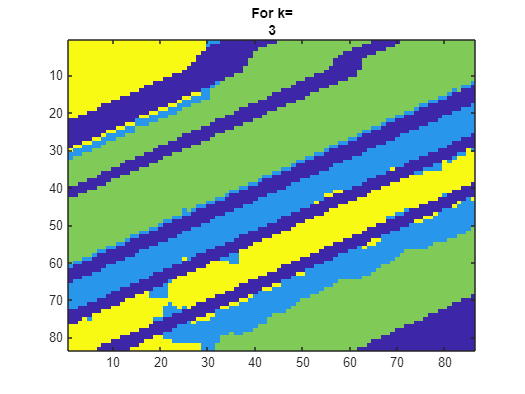

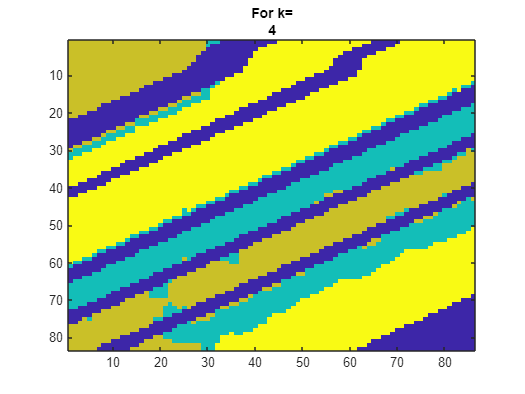

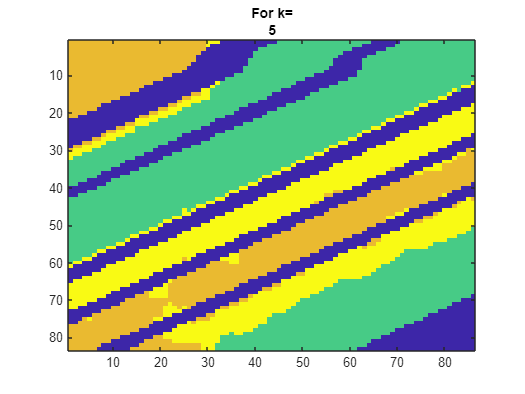

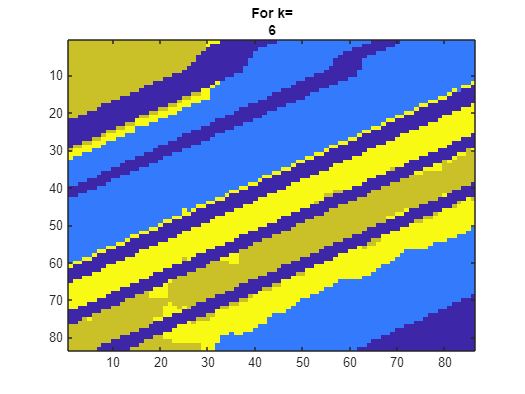

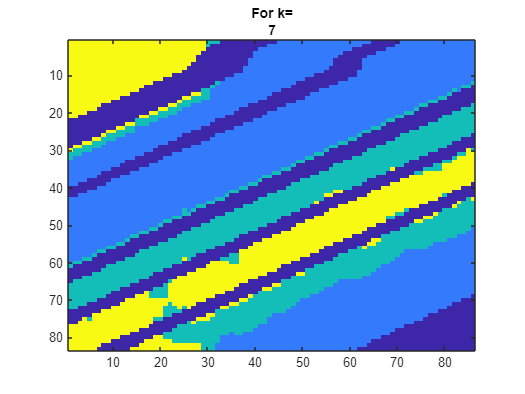

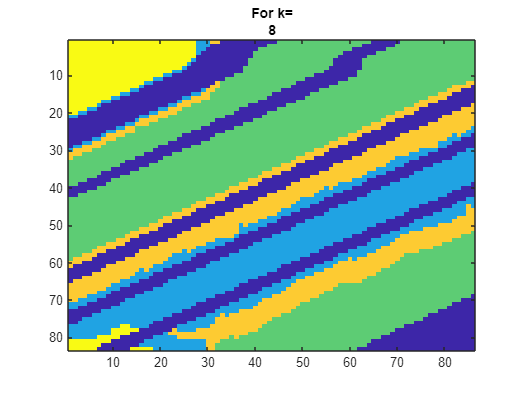

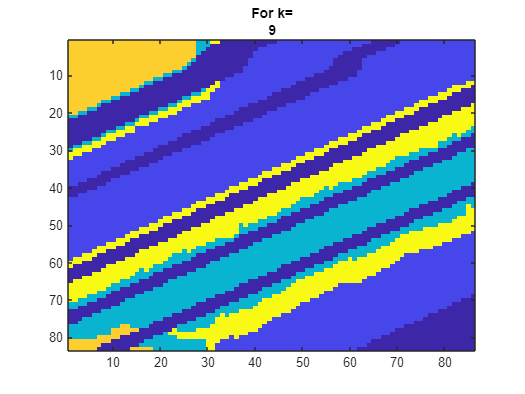

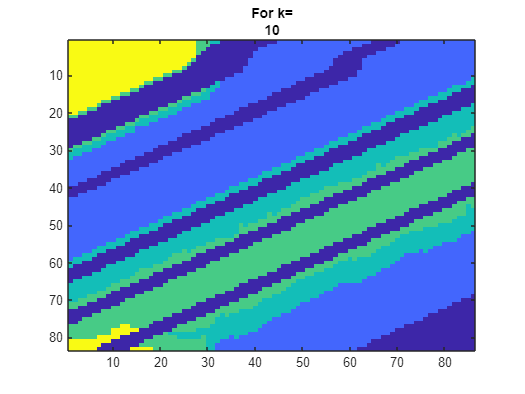

%% Filtering and Normalization %%

X=imgaussfilt(X,3.5,'FilterSize',9);
X=normalize(X);

%% Dimensionality Reduction with PCA %%

[eigenval,eigenvec,explain,Y,mean_vec]=pca_fun(X,n);
X=Y;
[l,N]=size(X);

rand_k_means_all=[];
jaccard_k_means_all=[];

for m=k1:k2
    
    costs=[];
    bels=[];

    for i=1:20
        theta_init=rand(l,m);
        [theta,bel,J]=k_means(X,theta_init);
        bels=[bels;bel];
        costs=[costs;J];
    end

    %figure(3),plot(costs)
    [cost_m,bel_index]=min(costs);
    bel=bels(bel_index,:);

    cl_label=bel';
    cl_label_tot=zeros(p1*n1,1);
    cl_label_tot(nonzero_idx)=cl_label;
    im_cl_label=reshape(cl_label_tot,p1,n1);
    figure(m), imagesc(im_cl_label);
    title(['For k=' {m}])

end

### **On Kennedy Space Center (KSC) Data**

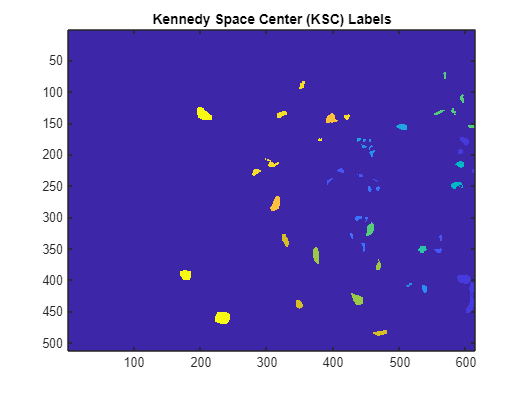

image = load("KSC.mat");
Image = image.KSC;
[p1,n1,l]=size(Image);
X=reshape(Image,p1*n1,l);
X=X';
gt = load("KSC_gt.mat");
Labels = gt.KSC_gt;
[p2,n2]=size(Labels);
y=reshape(Labels,p2*n2,1);
y=y';
zero_idx=find(~y);
nonzero_idx=find(y);
X(:,zero_idx)=[];
y(:,zero_idx)=[];
[l,N]=size(X);
%% Visualizations %%

im=Labels;
figure(1), imagesc(im);
title('Kennedy Space Center (KSC) Labels');
hold off

prompt = "What is the number of components? ";
n = input(prompt)

n = 13

prompt = "What is the lower k value? ";
k1 = input(prompt)

k1 = 5

prompt = "What is the higher k value? ";
k2 = input(prompt)

k2 = 20

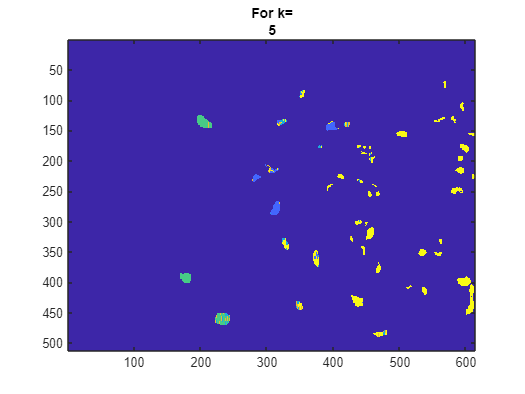

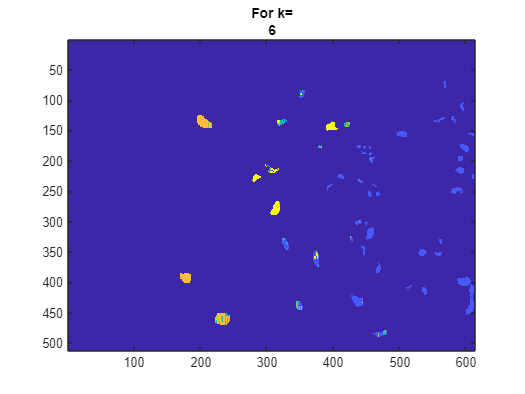

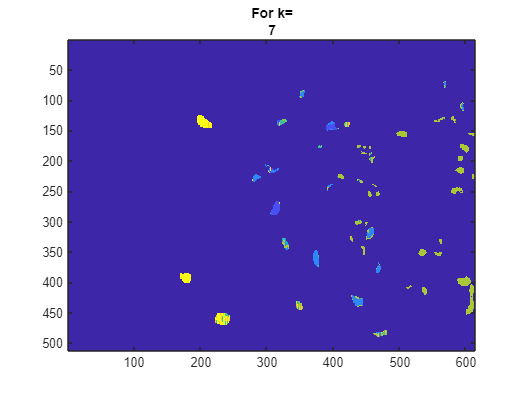

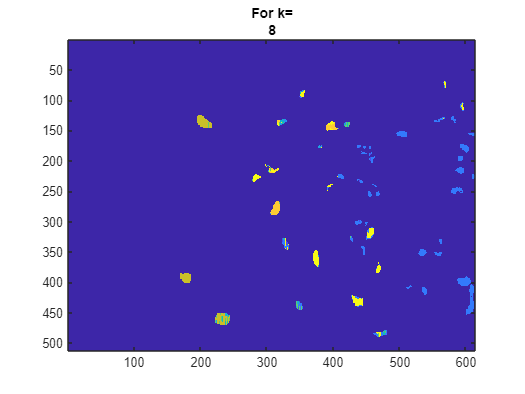

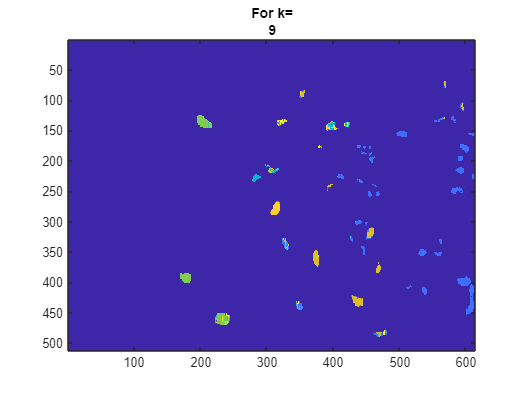

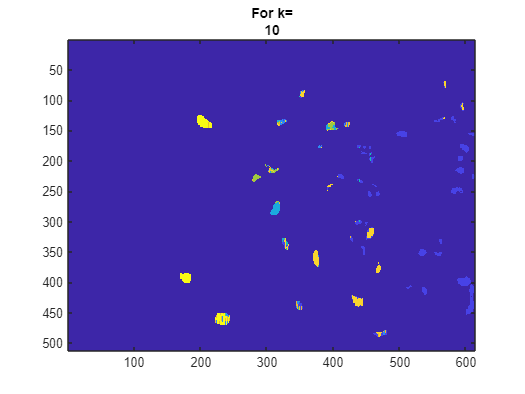

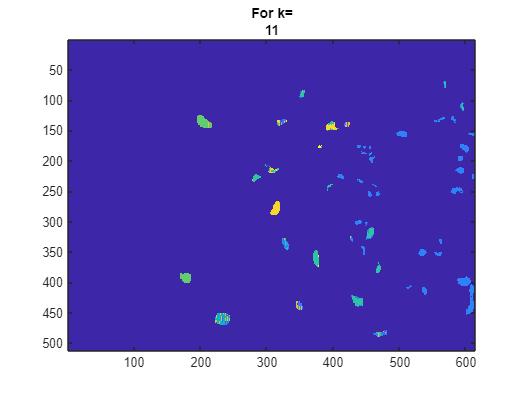

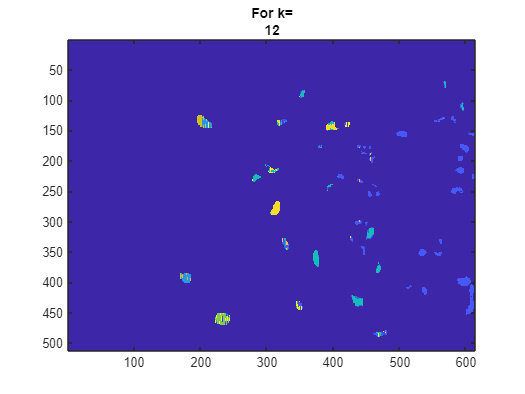

%% Filtering and Normalization %%

X=imgaussfilt(X,3.5,'FilterSize',9);
X=normalize(X);

%% Dimensionality Reduction with PCA %%

[eigenval,eigenvec,explain,Y,mean_vec]=pca_fun(X,n);
X=Y;
[l,N]=size(X);

rand_k_means_all=[];
jaccard_k_means_all=[];

for m=k1:k2
    
    costs=[];
    bels=[];

    for i=1:20
        theta_init=rand(l,m);
        [theta,bel,J]=k_means(X,theta_init);
        bels=[bels;bel];
        costs=[costs;J];
    end

    %figure(3),plot(costs)
    [cost_m,bel_index]=min(costs);
    bel=bels(bel_index,:);

    cl_label=bel';
    cl_label_tot=zeros(p1*n1,1);
    cl_label_tot(nonzero_idx)=cl_label;
    im_cl_label=reshape(cl_label_tot,p1,n1);
    figure(m), imagesc(im_cl_label); 
    title(['For k=' {m}])

end

function [theta,bel,J]=k_means(X,theta)

% Get the dimensions of the input matrix X and the centroid matrix theta
[l,N]=size(X);
[l,m]=size(theta);

% Set some convergence criteria and iteration limits
e=1;
iter=0;
e_thres=0.001;
max_iter=100;
while(e>e_thres && iter<max_iter)
    iter=iter+1;
    theta_old=theta;
    dist_all=[];

    % Compute the distance between each data point and each centroid
    for j=1:m
        p=ones(N,1)*theta(:,j)';
        q=X';
        
        % Squared Euclidean Distance
        dist=sum(((p-q).^2)');
        
        % Canberra Distance
        %dist=sum((abs(p-q)./(abs(p)+abs(q)))');
        
        % Add the distances to the dist_all matrix
        dist_all=[dist_all; dist];
    end
    
    % Find the index of the centroid that is closest to each data point
    [q1,bel]=min(dist_all);

    % Find the index of the centroid that is closest to each data point
    J=sum(min(dist_all));
   
    % Update each centroid to be the mean of the data points that are closest to it
    for j=1:m
        if(sum(bel==j)~=0)
            theta(:,j)=sum(X'.*((bel==j)'*ones(1,l))) / sum(bel==j);
        end
    end

     % Compute the difference between the old and new centroids
    e=sum(sum(abs(theta-theta_old)));
end
end
